# Plot Electricity Usage

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

dates = readmatrix("./data/electricityData.xlsx", Sheet="dates", OutputType="datetime");
sectors = readmatrix("./data/electricityData.xlsx", Sheet="sectors", OutputType="string");
usage = readmatrix("./data/electricityData.xlsx", Sheet="usage");
whos

  Name           Size            Bytes  Class       Attributes

  dates        315x1              2520  datetime              
  sectors        1x4               360  string                
  usage        315x4             10080  double                



usagesmooth = movmean(usage, 24);
totalSm = usagesmooth(:, end);
sectorUsageSm = usagesmooth(:, 1:3);

## Task 1

The goal of this interaction is to create the following plot of electricity usage:

You can use the `yyaxis` command to create separate axes on the left and right.

`yyaxis` `left`

`plot``(``x1``,``y1``)`

`yyaxis` `right`

`plot``(``x2``,``y2``)`

yyaxis left
plot(dates, sectorUsageSm)
grid minor
yyaxis right
plot(dates, totalSm)

Do not edit. This code adds a legend.

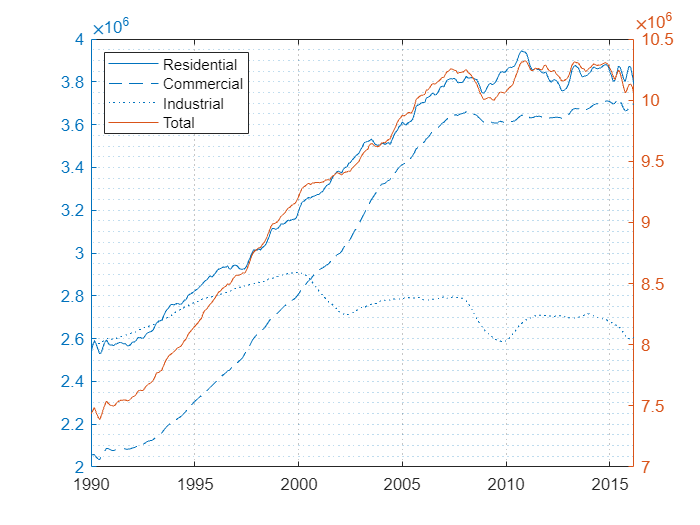

legend(sectors, "Location", "northwest")